clear


## CLOSED LOOP DC MOTOR

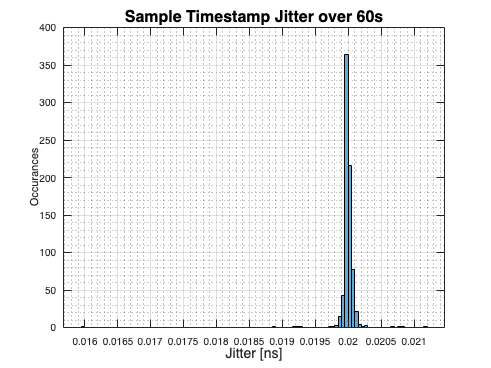

[~, cl_ramp_rpm, cl_ramp_ref, cl_ramp_u] = extractMotorData("DataSets/cl_zn_ramp10.csv");
[timestamps, cl_step_rpm, cl_step_ref, cl_step_u ] = extractMotorData("DataSets/cl_zn_step.csv");
[~, cl_chirp_rpm, cl_chirp_ref, cl_chirp_u] = extractMotorData("DataSets/cl_zn_chrip8_1.csv");

%Calcualte Sample time Jitter
histogram(diff(timestamps)*10^-9); grid on; grid minor; 
xlabel("Jitter [ns]", 'FontSize', 14); ylabel('Occurances'); title('Sample Timestamp Jitter over 60s', 'FontSize',16);

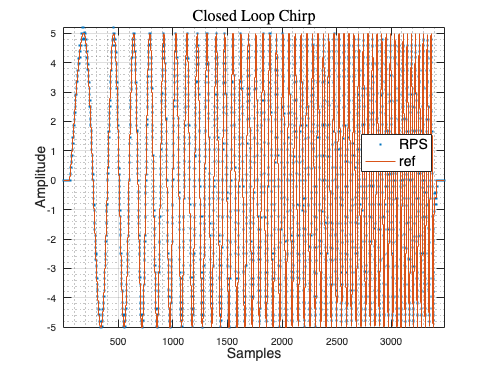

graphData(cl_chirp_rpm, cl_chirp_ref, 'Closed Loop Chirp');

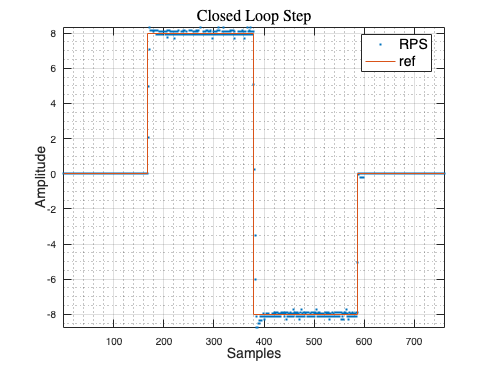

graphData(cl_step_rpm, cl_step_ref, 'Closed Loop Step');

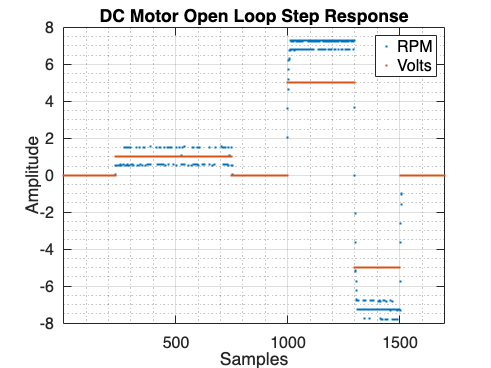

%% Open Loop DC Motor
[~, ramp_rpm, ramp_volt, ~] = extractMotorData("DataSets/ramp10_100.csv");
[~, sin1_1_rpm, sin1_1_volt, ~] = extractMotorData("DataSets/sin_1_1_100.csv");
[~, sin5_5_rpm, sin5_volt, ~] = extractMotorData("DataSets/sin_5_5_100.csv");
[~, sin1_8_rpm, sin1_8_volt, ~] = extractMotorData("DataSets/sin_1_8_100.csv");
[~, chirp_rpm, chirp_volt, ~] = extractMotorData("DataSets/chirp_1_10_100.csv");
[~, step_rpm, step_volt, ~] = extractMotorData("DataSets/openStep.csv");
[~, trig_rpm, trig_volt, ~] = extractMotorData("DataSets/openTrig.csv");

fig = figure;
plot(step_rpm(200:end), '.'); hold on; plot(step_volt(200:end), '.'); hold off; legend("RPM", "Volts"); grid on; grid minor;fontsize(16,"points");
title("DC Motor Open Loop Step Response"); xlabel("Samples"); ylabel("Amplitude"); xlim([1,1700]);

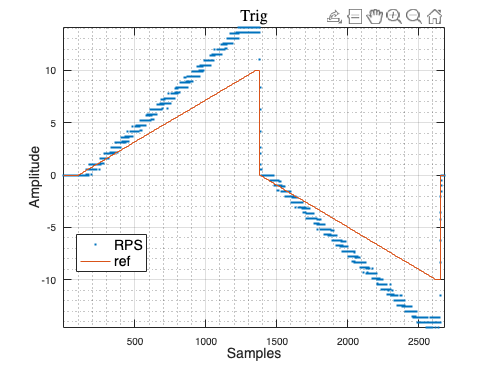

% Plot datasets
% Trig
graphData(trig_rpm, trig_volt, 'Trig')

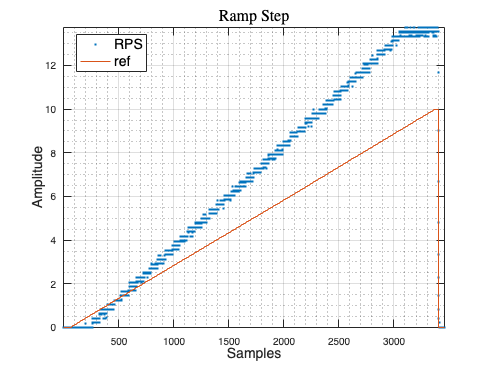



% Ramping Step Plot
graphData(ramp_rpm, ramp_volt, 'Ramp Step')

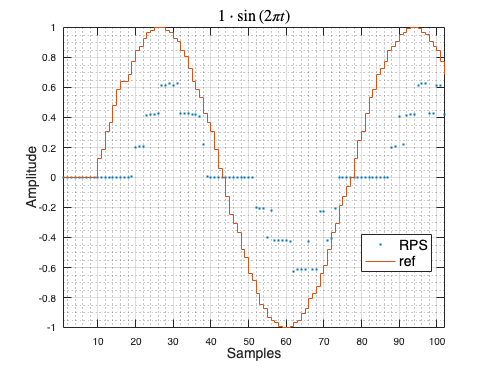

% 1Hz Sine
graphData(sin1_1_rpm(100:201), sin1_1_volt(100:201), '$1\cdot \sin{(2\pi t)}$')

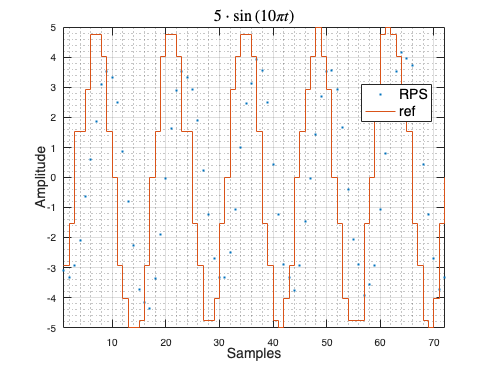

% 5Hz Sine Plot
graphData(sin5_5_rpm(75:146), sin5_volt(75:146), '$5\cdot \sin{(10\pi t)}$')

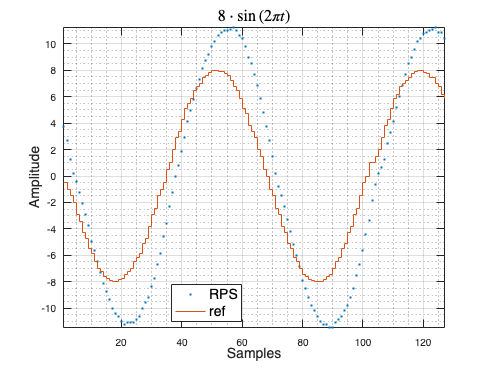

% 8Hz Sine Plot
graphData(sin1_8_rpm(75:201), sin1_8_volt(75:201), '$8\cdot \sin{(2\pi t)}$')

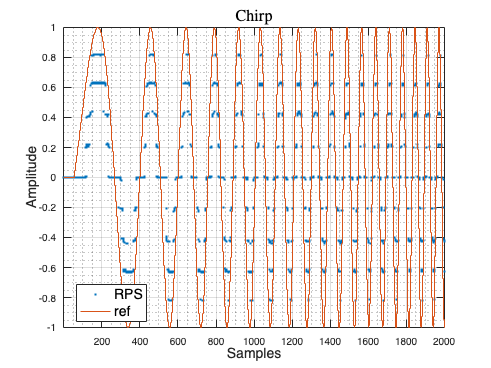

% Chirp Plot (Spanning two columns)
graphData(chirp_rpm(1:2001), chirp_volt(1:2001), 'Chirp')

% Inoput output plotting helper
function graphData(outputData,inputData, title)
  stairs(outputData,  '.');
hold on;
stairs(inputData,  '-');
hold off;
grid on; grid minor;
subtitle(title, 'FontSize', 16, 'Interpreter','latex'); 
legend("RPS", "ref", 'FontSize', 14, 'Location', 'best');
xlabel('Samples', 'FontSize',14);
ylabel('Amplitude', 'FontSize',14);
axis tight;
end
